%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The data_dir variable is the only input allowed to your code. 
% Do not modify any file names in the image directory.
data_dir = "./MASI_pets";
% Add your code below.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Task 1: Scan the image files to gather image meta data.

% Gets a list of all files in image directory with specified extensions
files = dir(data_dir);
files = [dir('*.jpg'); dir('*.png'); dir('*.jpeg'); dir('*.jfif')];

numFiles = length(files);

% Creates and initializes vectors to store image metadata
fileName = strings([numFiles,1]);
imageName = strings([numFiles,1]);
imageDimensions = zeros(numFiles,3);
imageSize = zeros(numFiles,1);
aspectRatio = zeros(numFiles,1);
petName = strings([numFiles,1]);
ownerInitials = strings([numFiles,1]);

% loops through all images in image directory
for i = 1:numFiles
    
    % stores file names (used later in Task 3)
    fileName(i) = files(i).name;
    
    image = imread(fileName(i));

    % stores image name
    imageName(i) = extractBefore(fileName(i), '.');

    % stores image dimensions
    imageDimensions(i,:) = size(image);

    % stores image size
    imageSize(i) = imageDimensions(i,1) * imageDimensions(i,2);

    % stores image aspect ratio
    aspectRatio(i) = imageDimensions(i,2)/imageDimensions(i,1);

    % stores pet name
    petName = extractBefore(imageName, '_');

    % stores owner initials
    ownerInitials = extractAfter(imageName, '_');
    
end

% creates and displays table with all image metadata, sorted primarily by
% descending image size and secondarily by ascending pet name
metaDataTable = table(imageName, imageDimensions, imageSize, aspectRatio, petName, ownerInitials);
sortedTable = sortrows(metaDataTable, ["imageSize", "petName"], ["descend", "ascend"]);
disp(sortedTable);

           imageName             imageDimensions       imageSize     aspectRatio          petName           ownerInitials
    _______________________    ____________________    __________    ___________    ____________________    _____________

    "Yasha_SR"                 4608    3456       3    1.5925e+07         0.75      "Yasha"                     "SR"     
    "Arthur_FR"                4032    3024       3    1.2193e+07         0.75      "Arthur"                    "FR"     
    "August_XY"                4032    3024       3    1.2193e+07         0.75      "August"                    "XY"     
    "Disney_XY"                3024    4032       3    1.2193e+07       1.3333      "Disney"                    "XY"     
    "Francie_CK"               4032    3024       3    1.2193e+

## Task 2: Look at the meta data to assess differences in the dataset.

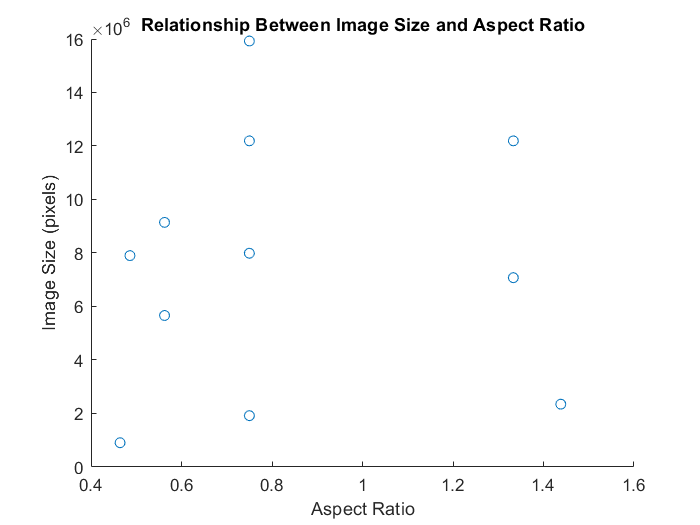

% creates a scatter plot comparing image size with aspect ratio across all
% images
scatter(aspectRatio, imageSize);
title('Relationship Between Image Size and Aspect Ratio');
xlabel('Aspect Ratio');
ylabel('Image Size (pixels)');

## Task 3: Look at the image data to check quality.

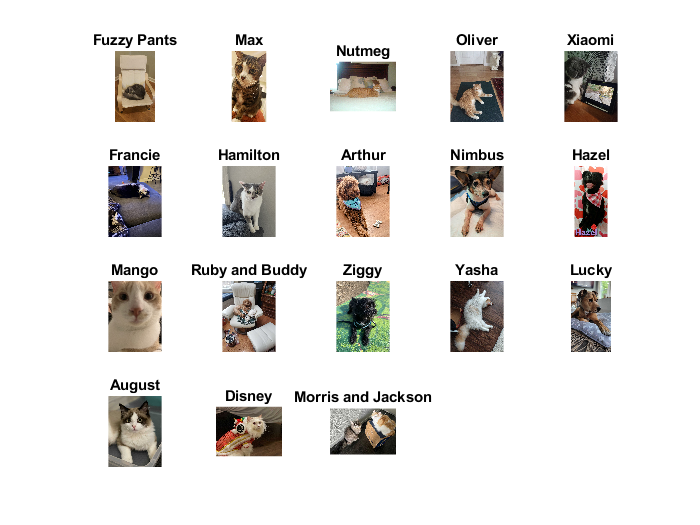

% adds a column to the dataset with filenames so that the images can be
% sorted and displayed in the correct order
metaDataTable.fileName = fileName;
metaDataTable = sortrows(metaDataTable, ["ownerInitials", "petName"]);

% loops through all images and displays them as subplot within single
% figure
for i = 1:numFiles
    image = imread(metaDataTable.fileName(i));
    % adds image as subplot to 4x5 grid from left to right and from up to
    % down
    subplot(4,5,i)
    imshow(image)
    title(metaDataTable.petName(i));
end